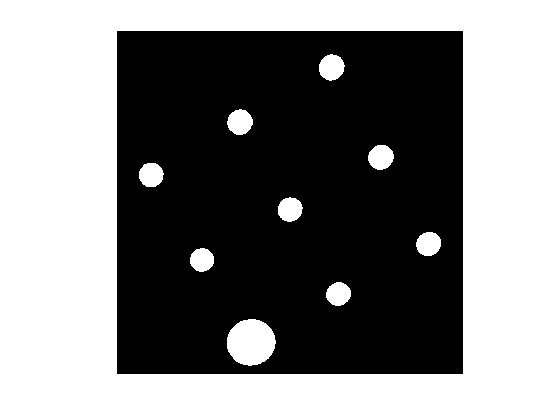

clear All; close all; clc;

img = imread("test_images/test_01.png");

% Get hue value
[H,S,V] = rgb2hsv(img);
% Examine the image and binarize blue area
blue = H>0.65 & H<0.68;

% Clean noise
blueClean = medfilt2(blue, [5,5]);

% Get props' centroids
stats = regionprops("table",blueClean,"Centroid");
% Store data
centroids = cat(1,stats.Centroid);
binary_img = blueClean;